José Francisco Altamirano Zevallos

t0 = 1;
tf = 2;
y10 = 0;
y21 = 0;
N = 100;
h = (tf-t0)/(N-1);

f = @(t,y1y2) [4/t^3 - 2*y1y2(2)/t^3; -(exp(y1y2(1)))];
g = @(s) shooting2(f,t0,tf,y10,y21,h,s);
%Si en lugar de hacerlo función, le metiera aux = shooting2(f,t0,tf,y10,y21,h,s); podría ver que regresa cada aproximación

[y20,i] = FuncionBiseccion(g,0,4); 

ans = 0


y1y20 = [y10,y20];

y1y20 =          0    1.5000


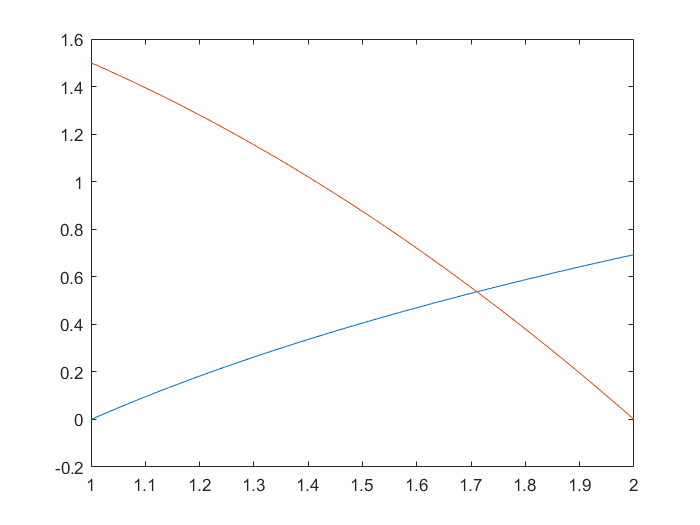


[t,y1y2] = ivps (f, t0, tf, y1y20, h, 5);

plot(t,y1y2(1,:)); 
hold on;
plot(t,y1y2(2,:)); 


yf =y1y2(:,end)

yf =     0.6931
   -0.0000
